clear all
tic

% Define the dimension and limits for 3D integration
d = 3;
a = [0, 0, 0];  % Lower limits for each dimension
b = [1, 1, 1];  % Upper limits for each dimension
tol = 1e-3;     % Tolerance for error

% Define the integrand functions
integrand_func = func3(d);
integrand_func_builtin = func3_for_builtin(d);

% Calculate the known integral value using MATLAB's built-in functions
%builtin_integral = integral3(integrand_func_builtin, a(1), b(1), a(2), b(2), a(3), b(3));

if d == 1
    builtin_integral = integral(integrand_func_builtin, a(1), b(1));
elseif d == 2
    builtin_integral = integral2(integrand_func_builtin, a(1), b(1), a(2), b(2));
elseif d == 3
    builtin_integral = integral3(integrand_func_builtin,a(1), b(1), a(2), b(2), a(3), b(3));
end


% Initialize variables for tracking

eva_size_SG = 1:500;  % Number of levels
errors_SG = zeros(size(eva_size_SG));  % Preallocate array for errors


func_evals_SG = zeros(size(eva_size_SG)); % To track function evaluations for Smolyak Grid



a = 0;
b = 1;


for i = 1:length(eva_size_SG)
    num_levels = eva_size_SG(i);
    %[integral_estimate_SG, func_evals_SG(i)] =
    %smolyak_trap_2d(integrand_func, a, b, eva_size_SG(i)); use this for 2D
    [integral_estimate_SG, func_evals_SG(i)] = smolyak_trap_3d(integrand_func, a, b, eva_size_SG(i));
    abs_diff = abs(builtin_integral - integral_estimate_SG);
    errors_SG(i) = abs_diff / abs(builtin_integral);

    % this is the test code for 100,000 num of evaluations
    % if func_evals_SG(i) > 100000
    %     eva_size_SG = eva_size_SG(1:i);  % Trim the excess preallocated space
    %     errors_SG = errors_SG(1:i);  % Trim the excess preallocated space
    %     func_evals_SG = func_evals_SG(1:i);  % Trim the excess preallocated space
    %     disp(integral_estimate_SG);
    %     disp('number of function evaluation is' +func_evals_SG(i));
    %     disp(errors_SG(i));
    %     break;
    % end

    %This is the test code for num_ function calls needed for tolerance level
    if errors_SG(i) < tol
        eva_size_SG = eva_size_SG(1:i);  % Trim the excess preallocated space
        errors_SG = errors_SG(1:i);  % Trim the excess preallocated space
        func_evals_SG = func_evals_SG(1:i);  % Trim the excess preallocated space
        disp("number of function evaluation is: " +func_evals_SG(i));
        disp("relative error: " + errors_SG(i));
        break;  % Exit the loop if the error is below the tolerance
    end
end

number of function evaluation is: 26496


relative error: 0.0009429


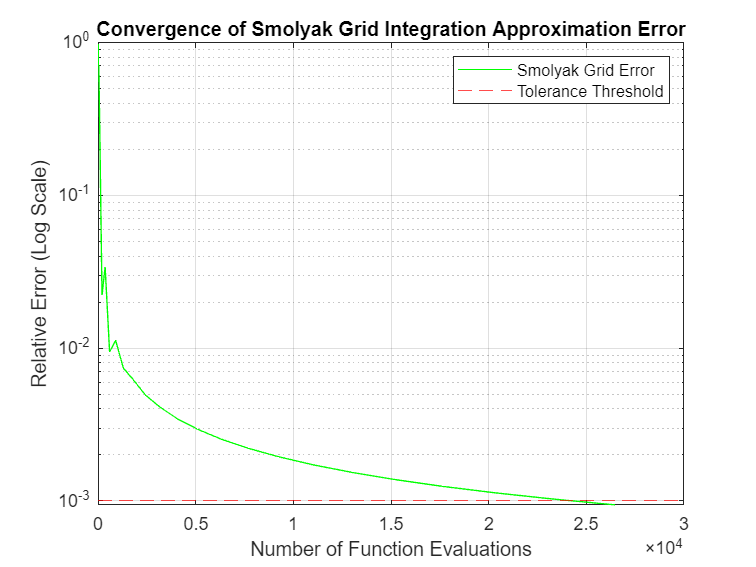


figure;
semilogy(func_evals_SG, errors_SG, 'g-', 'DisplayName', 'Smolyak Grid Error');
hold on;
yline(tol, 'r--', 'DisplayName', 'Tolerance Threshold');
hold off;
xlabel('Number of Function Evaluations');
ylabel('Relative Error (Log Scale)');
title('Convergence of Smolyak Grid Integration Approximation Error');
legend show;
grid on;

toc

Elapsed time is 2.511145 seconds.


3D Sparse Grid Method

function [I, num_func_evals] = smolyak_trap_3d(func, a, b, level)
    % Initialize integration result and function evaluation count
    I = 0;
    num_func_evals = 0;
    
    % Generate points for the first dimension
    x_points = linspace(a, b, level+1);
    
    % Iterate over each slice in the first dimension
    for i = 1:length(x_points)
        % For each slice in x, define a 2-D function to integrate over y and z
        func2d = @(y, z) func([x_points(i)*ones(size(y)), y, z]);
        
        % Initialize integration result for the 2-D slice
        I_slice = 0;
        slice_evals = 0; % Initialize count of evaluations for this slice
        
        % Generate points for the second dimension
        y_points = linspace(a, b, level+1);
        
        % Iterate over each slice in the second dimension
        for j = 1:length(y_points)
            % For each slice in y, define a 1-D function to integrate over z
            func1d = @(z) func2d(y_points(j), z);
            
            % Integrate this function over the third dimension (z) and get evaluation count
            [I_subslice, subslice_evals] = trapezoidal_rule(func1d, a, b, level);
            
            % Update the total evaluations for the slice
            slice_evals = slice_evals + subslice_evals;
            
            % Apply trapezoidal rule weighting for the y dimension
            weight_y = 1;
            if j == 1 || j == length(y_points)
                weight_y = 0.5;
            end
            
            % Add weighted subslice to the 2-D slice integration
            I_slice = I_slice + I_subslice * weight_y;
        end
        
        % Apply trapezoidal rule weighting for the x dimension
        weight_x = 1;
        if i == 1 || i == length(x_points)
            weight_x = 0.5;
        end
        
        % Add weighted 2-D slice to total integration and update total function evaluations
        I = I + I_slice * weight_x;
        num_func_evals = num_func_evals + slice_evals;
    end
    
    % Multiply by step sizes (assumes uniform spacing)
    h_x = (b - a) / level;
    h_y = (b - a) / level;
    I = I * h_x * h_y;
end


function [integral, func_evals] = trapezoidal_rule(func, lowerBound, upperBound, n)
    % Calculate the width of each trapezoid
    h = (upperBound - lowerBound) / n;
    
    % Initialize the sum with the first and last terms
    sum = func(lowerBound) + func(upperBound);
    func_evals = 2; % Counting the first and last evaluations
    
    % Sum up all the middle terms
    for i = 1:n-1
        x = lowerBound + i * h;
        sum = sum + 2 * func(x);
        func_evals = func_evals + 1; % Increment for each middle term evaluated
    end
    
    % Double the middle terms' evaluation count since they're counted twice in the trapezoidal sum
    func_evals = func_evals + (n - 1);
    
    % Finalize the calculation
    integral = (h / 2) * sum;
end

2D Sparse Grid Method

function [I, num_func_evals] = smolyak_trap_2d(func, a, b, level)
    % Simplified 2-D Smolyak-like algorithm using trapezoidal rule
    % func: 2-D function to integrate
    % a, b: Integration limits for both dimensions
    % level: Number of intervals in one dimension (N+1 points)

    % Initialize integration result and function evaluation count
    I = 0;
    num_func_evals = 0;

    % Generate points and intervals for one dimension
    x_points = linspace(a, b, level+1);
    
    % Apply trapezoidal rule in one dimension
    for i = 1:length(x_points)
        % Define a 1-D function for the current slice
        func1d = @(y) func([x_points(i), y]);
        
        % Integrate this function over the other dimension and get evaluations
        [I_slice, slice_evals] = trapezoidal_rule(func1d, a, b, level);
        
        % If it's the first or last slice, weight by 1/2 (trapezoidal rule end points)
        weight = 1;
        if i == 1 || i == length(x_points)
            weight = 0.5;
        end
        
        % Add weighted slice to total integration
        I = I + I_slice * weight;

        % Update total function evaluations
        num_func_evals = num_func_evals + slice_evals;
    end
    
    % Multiply by step size (assumes uniform spacing)
    h = (b - a) / level;
    I = I * h;
end

